# Local Passivity Enforcement

## Introduction

Local passivity enforcement is an enforcement method based on positive realness [1]. The main idea is to sample the Popov function 

$\Psi(s) = H(s) + H^\mathrm{T}(-s)$,

at a predefined set of frequencies along the imaginary axis and check its definiteness. The system is positive real if

$\min \lambda(\Psi(j\omega)) \ge 0 \quad \forall \;\omega $.

At every frequency where the positive realness condition is violated, a constraint is necessary that ensures a positive semidefinite Popov function after perturbation. Eigenvalue perturbation can be formulated as 

$\hat{\lambda}_k \approx \lambda_k + v^\mathrm{H}_k \Delta \Psi v_k$,

where $\Delta \Psi = \Delta H(s) + \Delta H^\mathrm{T}(-s)$. We set up a quadratic program that looks for the minimum perturbation that satisfies the positive realness constraints

$\min_\xi ||\xi||^2_2 \quad \text{s.t.} \quad Z\xi \ge -\lambda$.

Here, all information on the constraints in the correct format is present in $Z$ and $\lambda$. To make the approach $\mathcal{H}_2$-optimal, a coordinate change is utilized. Since perturbation of the eigenvalues is only an approximation the approach is applied iteratively.

### Pseudo-Code

## Toolbox Implementation

The MORpH toolbox provides an implementation of local passivity enforcement in the function *locPasEnf*.

For more information, refer to the documentation:

help locPasEnf

  locPasEnf - Enforce passivity of sys by applying local passivity constraints
 
  Syntax:
    sysp = locPasEnf(sys)
    sysp = locPasEnf(sys,opts)
 
  Description:
        sysp = locPasEnf(sys,opts) perturbs matrix C of sys to obtain a
        passive model sysp by applying local constraints on the Popov
        function.
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:      sss object, containing LTI system
        *Optional Input Arguments:*
        - opts:  structure with execution parameters
            - .maxIter: 	Maximum number of iterations
                            [{500} / positive integer]
            - .step:        Factor controlling how much matrix C is perturbed.
                            [{0.5} / double]
            - .verbose:     Control console output.
                            [{0} / 1]
            - .makePH:    	Construct port-Hamiltonian system.
                      

## Example

The example considered here is a SISO Ladder Network with an architecture as shown below:  

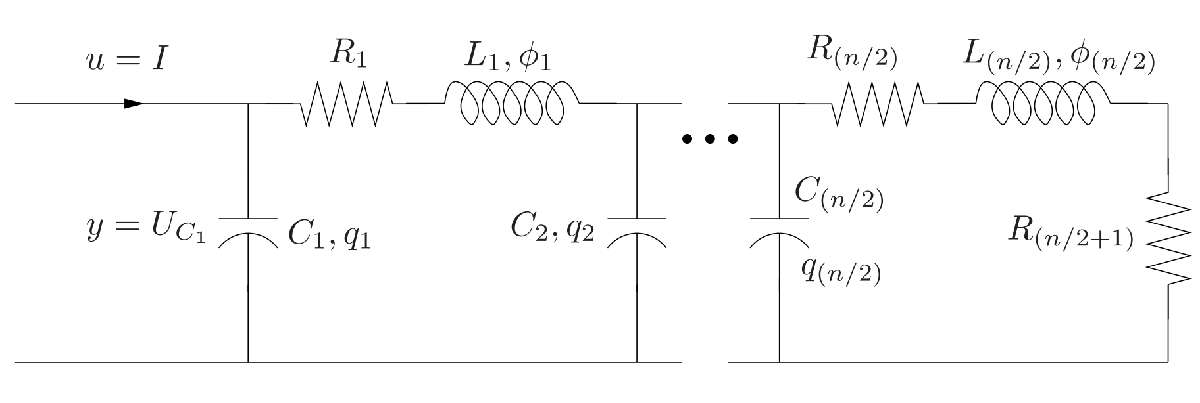

Image source: [2]

We consider a model with dimension $n = 100$, i.e. 50 inductances ($L_i = 0.2\text{H}$), 50 capacitors ($C_i = 0.2\text{F}$) and 51 resistances ($R_i=1\Omega$).

sys = sss(setup_LadderNetworkSystem(100,.2,.2,1))

sys =   (SSS)(SISO)
  100 state variables, 1 inputs, 1 outputs
  Continuous-time state-space model.


We reduce the 

sysr = irka(sys,10,struct('stopCrit','s0','maxiter',200,'tol',1e-5))

IRKA step 024 - Convergence (s0):  7.4e-06 

sysr =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8         x9        x10
   x1   -0.007913   -0.01923   -0.02042   -0.01829   -0.01677   -0.01837   -0.01305   0.003374   0.006377   0.001224
   x2    -0.01923    -0.1307    -0.1845     -0.164    -0.1477    -0.1599    -0.1132    0.02827    0.05229   0.007982
   x3    -0.02042    -0.1845    -0.4929    -0.5497    -0.4592    -0.4668    -0.3269     0.0698     0.1137  -0.007335
   x4    -0.01829     -0.164    -0.5497     -1.068     -1.021    -0.7652    -0.4986    0.04376   -0.06328    -0.1843
   x5    -0.01677    -0.1477    -0.4592     -1.021     -1.503    -0.6936     0.1163    -0.2264     -1.252    -0.7925
   x6    -0.01837    -0.1599    -0.4668    -0.7652    -0.6936     0.6258      2.546     -1.474     -3.815     -1.667
   x7    -0.01305    -0.1132    -0.3269    -0.4986     0.1163      2.546      4.625     -2.768     -3.995   -0.06642
   

isPassive(ss(sysr))

ans = logical
   0


*locPasEnf* in its simplest form is called by providing the non-passive system: 

warning('off','all')
sysp = locPasEnf(sysr)

	 Algorithm converged.

sysp =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8         x9        x10
   x1   -0.007907   -0.01869    -0.0157   0.001062    0.03293    0.05529    0.04324   -0.02591   -0.04069    0.01246
   x2    -0.01927    -0.1284    -0.1551   -0.02075      0.256     0.4706     0.3604    -0.2071    -0.3268     0.1113
   x3    -0.02055    -0.1823    -0.4455    -0.2397     0.5928      1.377      1.041    -0.5284     -0.901     0.2728
   x4    -0.01836    -0.1629    -0.5173    -0.7644     0.4256      2.516      2.075    -0.7154     -1.805      -0.25
   x5    -0.01627    -0.1444    -0.4586     -1.004    -0.8864      2.469      3.692    -0.4678     -3.268     -3.357
   x6    -0.01797    -0.1595    -0.5064     -1.109     -2.123     -1.246       3.72     -1.856     -1.934     -2.437
   x7    -0.01447    -0.1284    -0.4077    -0.8925      -1.71     -3.861     -2.674     -2.947       1.43      10.02
   x8     0.00242    0.0

norm(ss(sys) - ss(sysp))

ans = 6.1287e-04

isPassive(ss(sysp))

ans = logical
   1


### Options

loc*PasEnf* options are:

- Top level (loc*PasEnf*): e.g. step length

- Second level (*samPassive*): e.g. turn plotting Popov function on/off

- Third level (*phs*): e.g. switching on/off input validation

You can find more information on the respective options by having a look at the documentation, e.g.

help ss2phs

  ss2phs - Returns pH system representation of a given passive system
 
  Syntax:
    sysPH = ss2phs(sys)
    sysPH = ss2phs(sys,X)
    sysPH = ss2phs(sys,Opts)
    sysPH = ss2phs(sys,X,Opts)
 
  Description:
        This funciton uses the Kalman-Yakubovic-Popov Lemma to construct a
        port-Hamiltonian system representation of a given passive
        ss object.
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:  ss object to be brought in pH representation
        *Optional Input Arguments:*
        - X: solution to positive real Riccati equation
        - Opts: structure with execution parameters
            - .tol:             If D+D' is not positive definite, D is replaced
                                by Opts.tol*eye(m).
                                [{1e-12} / positive double]
            - .representation:  Defines the pH system representation
                       

To provide these options, use nested structs. As example, the following code changes the reduced system to be port-Hamiltonian:

Opts = struct();
Opts.makePH = true;     % Return pH system
Opts.ss2phs.method = @locPasEnf; % Reduction method for info
Opts

Opts = struct with fields:
    makePH: 1
    ss2phs: [1×1 struct]


sysp = locPasEnf(sysr,Opts)

	 Algorithm converged.


sysp =   phsRed with properties:

      parameters: [1×1 struct]
          method: @locPasEnf
            info: []
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 1
           isDAE: 0
    hasStaircase: 1


norm(ss(sys) - ss(sysp))

ans = 6.1409e-04

### Output

*locPasEnf* provides only the passive system as output. This ssRed/phsRed object contains additional information which makes the creation more transparent:

sysp.method    % Method with which the system was created (should be @locPasEnf)

ans = function_handle with value:
    @locPasEnf


sysp.parameters     % Execution parameters (options)         

ans = struct with fields:
        makePH: 1
        ss2phs: [1×1 struct]
    samPassive: [1×1 struct]
             w: [1.0000e-15 1.5923e-15 2.5354e-15 4.0370e-15 6.4281e-15 1.0235e-14 1.6298e-14 2.5950e-14 4.1320e-14 6.5793e-14 1.0476e-13 1.6681e-13 2.6561e-13 4.2292e-13 6.7342e-13 1.0723e-12 1.7074e-12 2.7186e-12 4.3288e-12 6.8926e-12 1.0975e-11 … ]
            w0: [1.0000e-15 1.0093e-15 1.0186e-15 1.0280e-15 1.0375e-15 1.0471e-15 1.0568e-15 1.0666e-15 1.0765e-15 1.0864e-15 1.0965e-15 1.1066e-15 1.1169e-15 1.1272e-15 1.1377e-15 1.1482e-15 1.1588e-15 1.1695e-15 1.1804e-15 1.1913e-15 1.2023e-15 … ]
       verbose: 0
          step: 0.5000
       maxIter: 500
      quadprog: [1×1 optim.options.Quadprog]


## References

[1] Grivet-Talocia, Gustavsen, "Passive Macromodeling Theory and Applications", 2016

[2] R. V. Polyuga, "Model reduction of port-Hamiltonian systems", PhD thesis, University of Groningen, 2010.

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Maximilian Bonauer    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)